# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
kristen_file_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
json_text = fileread(kristen_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

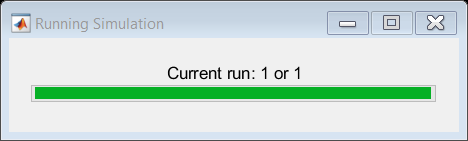

target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 83.33 MHz/us
	 Idle Time: 			 1.16 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 85.33 MSps
	 Ramp End Time: 		 18.32 us
	 Chirp Tx Bandwidth: 		 1526.37 MHz
	 Chirp Sampling Bandwidth: 	 1000.00 MHz
	 ADC Sampling Period: 		 12.00 us
	 Chirp Cycle Time: 		 19.48 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 4.99 ms
Performance Specifications
	 Max Range 			 153.49 m
	 Range Resolution 		 0.15 m
	 Max Velocity 			 49.97 m/s
	 Velocity Resolution 		 0.39 m/s
FMCW Specifications
	 FMCW sampling rate 		 1535.94 MHz
	 Downsampling factor 		 18
	 Sweep time 			 18.32 us
	 Samples per chirp 		 29916.00 


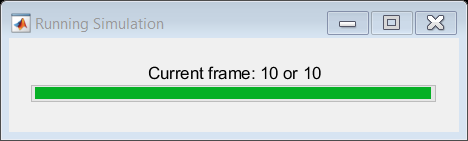

estimated_ranges =    81.1151       NaN       NaN       NaN       NaN
   82.1957       NaN       NaN       NaN       NaN
   83.3123       NaN       NaN       NaN       NaN
   84.4166       NaN       NaN       NaN       NaN
   85.5252       NaN       NaN       NaN       NaN
   74.7627   86.6094       NaN       NaN       NaN
   75.4765   87.7119       NaN       NaN       NaN
   75.4394   88.8397       NaN       NaN       NaN
   75.6528   89.9199       NaN       NaN       NaN
   75.2589   90.9973       NaN       NaN       NaN


actual_ranges =    81.0000   82.1004   83.2008   84.3012   85.4016   86.5020   87.6023   88.7027   89.8031   90.9035


percent_error_ranges =     0.1151
    0.0953
    0.1115
    0.1155
    0.1236
   11.7393
   12.1259
   13.2633
   14.1503
   15.6446


estimated_velocities =   -32.8274       NaN       NaN       NaN       NaN
  -32.8682       NaN       NaN       NaN       NaN
  -32.7459       NaN       NaN       NaN       NaN
  -32.7641       NaN       NaN       NaN       NaN
  -32.8623       NaN       NaN       NaN       NaN
    7.0010  -32.8086       NaN       NaN       NaN
    7.0027  -32.7443       NaN       NaN       NaN
    7.0033  -32.8491       NaN       NaN       NaN
    7.0012  -32.8575       NaN       NaN       NaN
    7.0037  -32.7983       NaN       NaN       NaN


actual_velocities =    -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


percent_error_velocities =     0.1726
    0.1318
    0.2541
    0.2359
    0.1377
   40.0010
   40.0027
   40.0033
   40.0012
   40.0037


detected =      1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


false_positives =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


values =    86.5020  -33.0000    1.0000   74.7627   11.7393    7.0010   40.0010    1.0000
   87.6023  -33.0000    1.0000   75.4765   12.1259    7.0027   40.0027    1.0000
   88.7027  -33.0000    1.0000   75.4394   13.2633    7.0033   40.0033    1.0000
   89.8031  -33.0000    1.0000   75.6528   14.1503    7.0012   40.0012    1.0000
   90.9035  -33.0000    1.0000   75.2589   15.6446    7.0037   40.0037    1.0000


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, percent_error_ranges, percent_error_velocities, false_positives] = sim.simulation_results();

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end,1), estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), percent_error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), percent_error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)]
end

Organize data into table

bin_classification = cast(values(:,1)/10, "int16")';
table_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

Plot P(detection) and P(false positive) vs. Range

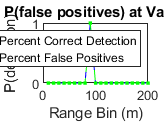

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if values(frame, 3)
                detected = detected + 1;
            end
            if values(frame, 8)
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")

Plot Error vs. Range

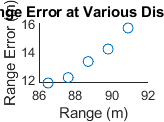

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    if (values(frame, 3) ~= 0)
        range_error_plot = [range_error_plot; [values(frame, 1), values(frame, 5)]];
    end
end
figure
scatter(range_error_plot(:,1), range_error_plot(:,2))
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")